# Integrate and Animate Chain Pendulum

clear;clc;

l1 = 5; l2 = 5; l3 = 5; l4 = 5; l5 = 5; 
c1 = l1/2; c2 = l2/2; c3 = l3/2; c4 = l4/2; c5 = l5/2; 
m1 = 0.5; m2 = 0.5; m3 = 0.5; m4 = 0.5; m5 = 0.5; 
I1 = 1/12 * m1 * l1^2; I2 = 1/12 * m2 * l2^2; I3 = 1/12 * m3 * l3^2; I4 = 1/12 * m4 * l4^2; I5 = 1/12 * m5 * l5^2;
g = 9.81;

## Integrate

T = 30;

% No external force tau = 0
s0 = [pi/2; 0; 0; 0; 0; 0; 0; 0; 0; 0];
tau = [0; 0; 0; 0; 0];
[t,s] = ode45(@(t,s) chain_pendulum_dynamics(s,tau),[0 T],s0);

## Animate 5 Link Pendulum

fps = 10;
tq = linspace(0,t(end), round(t(end)*fps));
data = zeros(length(tq),size(s,2));
for n=1:size(s,2)
    data(:,n) = interp1(t,s(:,n),tq);
end

% P0 = [0 0];
% figure(1);
% for k=1:size(data,1)
%     % E = T+V
%     E = chain_pendulum_energy(data(k,:));
%     
%     joint_pos = chain_pendulum_kinematics(data(k,1:5));
%     P1 = joint_pos(:,1);
%     P2 = joint_pos(:,2);
%     P3 = joint_pos(:,3);
%     P4 = joint_pos(:,4);
%     P5 = joint_pos(:,5);
%     
%     grid on;
%     hold on;  
%     h1 = line([P0(1) P1(1)], [P0(2) P1(2)], "LineWidth", 3);
%     h2 = line([P1(1) P2(1)], [P1(2) P2(2)], "LineWidth", 3);
%     h3 = line([P2(1) P3(1)], [P2(2) P3(2)], "LineWidth", 3);
%     h4 = line([P3(1) P4(1)], [P3(2) P4(2)], "LineWidth", 3);
%     h5 = line([P4(1) P5(1)], [P4(2) P5(2)], "LineWidth", 3);
%     
%     h6 = plot(P0(1), P0(2), 's', 'MarkerSize', 10, "LineWidth", 1, 'Color', 'black');
%     h7 = plot(P1(1), P1(2), '.', 'MarkerSize', 20, 'Color', 'black');
%     h8 = plot(P2(1), P2(2), '.', 'MarkerSize', 20, 'Color', 'black');
%     h9 = plot(P3(1), P3(2), '.', 'MarkerSize', 20, 'Color', 'black');
%     h10 = plot(P4(1), P4(2), '.', 'MarkerSize', 20, 'Color', 'black');
%     h11 = plot(P5(1), P5(2), '.', 'MarkerSize', 20, 'Color', 'black');
%     
%     h12 = text(-25, 25, ['Energy: ' num2str(E)]);
%     
%     axis([-30 30 -30 30]);
%     xticks(-30:5:30);
%     yticks(-30:5:30);
%     daspect([1 1 1]);
%     drawnow;
%     
%     % pause(0.1);
%     if k ~= size(data,1)
%         delete(h1); delete(h2); delete(h3); delete(h4); delete(h5); delete(h6);
%         delete(h7); delete(h8); delete(h9); delete(h10); delete(h11); delete(h12);
%     end
% end

## Initial Conditions for Constrained Loop Pendulum

x_hook = 15;
y_hook = 5;
hook_constraint = @(q) [x_hook;y_hook]-hook_position(q);

q_guess = [pi/4; 0.1;0.2; 0.3; 0.4];
options = optimset('Display','off','Algorithm','Levenberg-Marquardt');
[q_ik,val,flag] = fsolve(hook_constraint,q_guess,options);

## Integrate

T = 10;

% No external force tau = 0
s0 = [q_ik; 0; 0; 0; 0; 0];
tau = [0; 0; 0; 0; 0];
[t,s] = ode45(@(t,s) chain_pendulum_loop_dynamics(s),[0 T],s0);

## Animate 5 Link Constrained Loop Pendulum

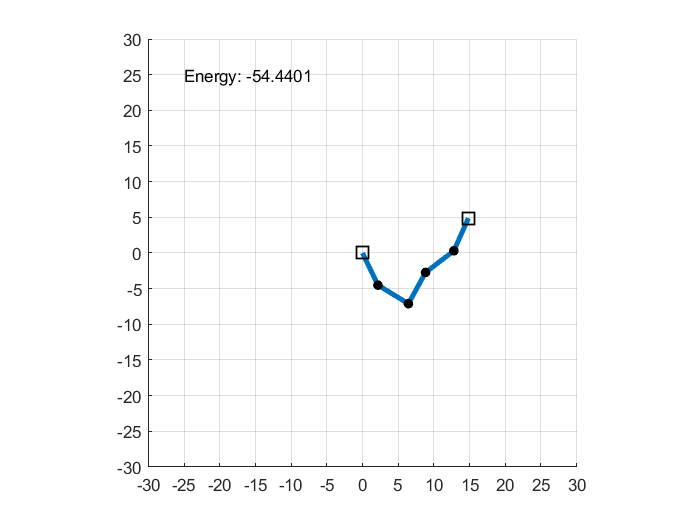

fps = 30;
tq = linspace(0,t(end), round(t(end)*fps));
data = zeros(length(tq),size(s,2));
for n=1:size(s,2)
    data(:,n) = interp1(t,s(:,n),tq);
end

P0 = [0 0];
figure(2);
for k=1:size(data,1)
    % E = T+V
    E = chain_pendulum_energy(data(k,:));
    
    joint_pos = chain_pendulum_kinematics(data(k,1:5));
    P1 = joint_pos(:,1);
    P2 = joint_pos(:,2);
    P3 = joint_pos(:,3);
    P4 = joint_pos(:,4);
    P5 = joint_pos(:,5);
    
    grid on;
    hold on;  
    h1 = line([P0(1) P1(1)], [P0(2) P1(2)], "LineWidth", 3);
    h2 = line([P1(1) P2(1)], [P1(2) P2(2)], "LineWidth", 3);
    h3 = line([P2(1) P3(1)], [P2(2) P3(2)], "LineWidth", 3);
    h4 = line([P3(1) P4(1)], [P3(2) P4(2)], "LineWidth", 3);
    h5 = line([P4(1) P5(1)], [P4(2) P5(2)], "LineWidth", 3);
    
    h6 = plot(P0(1), P0(2), 's', 'MarkerSize', 10, "LineWidth", 1, 'Color', 'black');
    h7 = plot(P1(1), P1(2), '.', 'MarkerSize', 20, 'Color', 'black');
    h8 = plot(P2(1), P2(2), '.', 'MarkerSize', 20, 'Color', 'black');
    h9 = plot(P3(1), P3(2), '.', 'MarkerSize', 20, 'Color', 'black');
    h10 = plot(P4(1), P4(2), '.', 'MarkerSize', 20, 'Color', 'black');
    h11 = plot(P5(1), P5(2), 's', 'MarkerSize', 10, "LineWidth", 1, 'Color', 'black');
    
    h12 = text(-25, 25, ['Energy: ' num2str(E)]);
    
    axis([-30 30 -30 30]);
    xticks(-30:5:30);
    yticks(-30:5:30);
    daspect([1 1 1]);
    drawnow;
    
    % pause(0.1);
    if k ~= size(data,1)
        delete(h1); delete(h2); delete(h3); delete(h4); delete(h5); delete(h6);
        delete(h7); delete(h8); delete(h9); delete(h10); delete(h11); delete(h12);
    end
end